# Computer Vision Concepts Implementation - Assignment 1 (8890 CVIA PG)

Author: Data Man

Date: 13/05/2022

## Dataset Preparation

% Set path for dataset folder
% path = "assets\CUB_200_2011\";
% nClass = 200;
path = "assets\CUB_200_2011_Subset20classes\";  % for debuging
nClass = 20;

% Show DL trainging info
verbose = false;

% Read image file paths
images = readtable(fullfile(path, "images.txt"), ...  
    "ReadVariableNames", false); 
images.Properties.VariableNames = ["index", "file"];

% Read object bounding box info
bboxes = readtable(path + "bounding_boxes.txt", ... 
    'ReadVariableNames', false);
bboxes.Properties.VariableNames = {'index', 'x', 'y', 'w', 'h'};
bm = mapBboxes(images(:, 2), bboxes(:, 2:5));

% Target size of input images
ts = [128, 128];
% ts = [256, 256];

% Datastore of full images
fids = imageDatastore(fullfile(path, "images", images.file), ...
    "labelSource", "foldernames");
fids.ReadFcn = @(file) readImages(file, ts);

% Datastore of cropped images (via bounding boxes)
cids = imageDatastore(fullfile(path, "images", images.file), ...
    "labelSource", "foldernames");
cids.ReadFcn = @(file) readImages(file, ts, bm);

% Split datasets
[trainFull, validateFull, testFull] = splitEachLabel(fids, 0.6, 0.2);
[trainCropped, validateCropped, testCropped] = splitEachLabel(cids, 0.6, 0.2);

% Split for 5-fold validation
[part1, part2, part3, part4, part5] = splitEachLabel(cids, 0.2, 0.2, 0.2, 0.2);

disp("Data preparation finish.")

Data preparation finish.


## Task 1: Classic Machine Learning Approach

In this task, the project choices classic HOG (Histogram of Oriented Gradient) features to identify the birds. The classifier selected is SVM (Support Vector Machine). In the first part, a random sample image was loaded and HOG features with cell size of 64 by 64, 16 by 16, and 4 by 4 were extracted for evaluation. In this test run, the target input image size was 128 by 128. It is clear that the cell size of [64 64] did not result in much information, while [4 4] encoded over 30,000. This will require computational power of multiple higher orders of magnitude. However, this project will evaluate all three of them in later sessions for comparison.

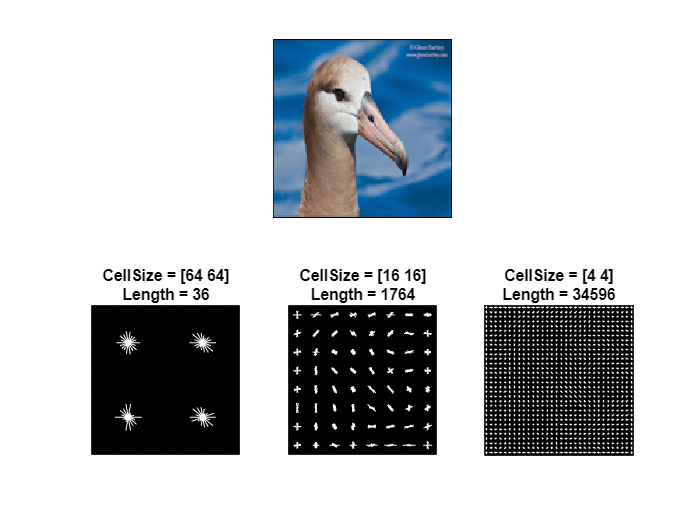

% Read sample image
img = fids.read();

% Extract HOG features and HOG visualization
[hog_64x64, vis64x64] = extractHOGFeatures(img, 'CellSize', [64 64]);
[hog_16x16, vis16x16] = extractHOGFeatures(img, 'CellSize', [16 16]);
[hog_4x4, vis4x4] = extractHOGFeatures(img, 'CellSize', [4 4]);

% Show the original image
figure; 
subplot(2,3,1:3); imshow(img);

% Visualize the HOG features
subplot(2,3,4);  
plot(vis64x64); 
title({'CellSize = [64 64]'; ['Length = ' num2str(length(hog_64x64))]});

subplot(2,3,5);
plot(vis16x16); 
title({'CellSize = [16 16]'; ['Length = ' num2str(length(hog_16x16))]});

subplot(2,3,6);
plot(vis4x4); 
title({'CellSize = [4 4]'; ['Length = ' num2str(length(hog_4x4))]});

% Set cell size of HOG features for experiments
cs = {[64 64] [16 16] [4 4]};
fs = {length(hog_64x64) length(hog_16x16) length(hog_4x4)};

## Task 2: Deep Learning Approach

A simple CNN (convolutional neural network) for deep learning classification was employed in this project. For this task, the input images are most coloured, so any grayscale images were concatenated into three layers of same gray pixel plains. There are seven convolutional layers with feature maps of 8, 16, 32, 64, 128, 256, 512, respectively. In the following max pooling layers, the size of rectangular regions were all [2, 2] to remove redundant information. In this test run, the output consist of 20 classes for the smaller dataset.

% Setup GPU
if (gpuDeviceCount() > 0)
    device = gpuDevice(1);
    reset(device);
end

% Network layers
layers = [
    imageInputLayer([ts 3])
    
    convolution2dLayer(3, 8, 'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3, 128, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3, 256, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3, 512, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(nClass)
    softmaxLayer
    classificationLayer];

## Whole Image as Input

### Experiment 1

disp("Experiment 1 start...")

Experiment 1 start...



% Conduct tests on differernt cell size
for i = 1:3
    disp("Test #" + string(i))
    cellSize = cs{i};
    featureSize = fs{i};
    disp("  Cell size: " + cellSize(1))
    disp("  Feature size: " + featureSize)
    runProcessML(trainFull, testFull, cellSize, featureSize);
end

Test #1


  Cell size: 64


  Feature size: 36


  Overall Accuracy: 9.3%


Test #2


  Cell size: 16


  Feature size: 1764


  Overall Accuracy: 14.2%


Test #3


  Cell size: 4


  Feature size: 34596


  Overall Accuracy: 12.4%



disp("Experiment 1 finish.")

Experiment 1 finish.


#### Discussion

In this test runs on 20 classes dataset, with full images, the accuracy sits around 11%. It is clear that the cell size of [64 64] shows worst performance because it only encoded 36 features. However, it is interesting the features size of over 30,000 did not result in better accuracy. This may comes from more noise picked up by the feature extraction. So the extra computational power invested is not worth it in this case.

### Experiment 2

disp("Experiment 2 start...")

Experiment 2 start...



% Combine datastores for the model
trainFullDS = combine(trainFull, arrayDatastore(trainFull.Labels));
validateFullDS = combine(validateFull, arrayDatastore(validateFull.Labels));
testFullDS = combine(testFull, arrayDatastore(testFull.Labels));

% Run deep learning training process
runProcessDL(layers, verbose, trainFullDS, validateFullDS, testFullDS);

  Overall Accuracy: 38.2%



disp("Experiment 2 finish.")

Experiment 2 finish.


#### Discussion

Although it is running on the same full image datastores, this simple CNN model shows much better result compare to HOG-based ML above. If the network were further tuned, the performance may even improve. With a well designed network the performance could improve significantly.

## Target Area Image as Input

### Experiment 3

disp("Experiment 3 start...")

Experiment 3 start...



% Conduct tests on differernt cell size
for i = 1:3
    disp("Test #" + string(i))
    cellSize = cs{i};
    featureSize = fs{i};
    disp("  Cell size: " + cellSize(1))
    disp("  Feature size: " + featureSize)
    runProcessML(trainCropped, testCropped, cellSize, featureSize);
end

Test #1


  Cell size: 64


  Feature size: 36


  Overall Accuracy: 6.7%


Test #2


  Cell size: 16


  Feature size: 1764


  Overall Accuracy: 16.9%


Test #3


  Cell size: 4


  Feature size: 34596


  Overall Accuracy: 19.1%



disp("Experiment 3 finish.")

Experiment 3 finish.


#### Discussion

With cropped images, the overall performance of this HOG-based ML model did improved, and the one with largest feature size gave the best performance among the three tests. This could comes from less noise presented in the image frame, so the features extracted did help the model. But this approach still worse than CNN with full image input above.

### Experiment 4

disp("Experiment 4 start...")

Experiment 4 start...



% Combine datastores for the model
trainCroppedDS = combine(trainCropped, arrayDatastore(trainCropped.Labels));
validateCroppedDS = combine(validateCropped, arrayDatastore(validateCropped.Labels));
testCroppedDS = combine(testCropped, arrayDatastore(testCropped.Labels));

% Run deep learning training process
runProcessDL(layers, verbose, trainCroppedDS, validateCroppedDS, testCroppedDS);

  Overall Accuracy: 42.7%



disp("Experiment 4 finish.")

Experiment 4 finish.


#### Discussion

The performance of this CNN network with cropped image inputs did improve but not much. Most of the images in this dataset are already quite clear and the target is the only major object in the frame, so a crop may not reduce the distraction. However, the deformation introduced by resizing may affect the performance of the model. The resolution is not very high in the first place, so the shape change could make some images very hard to process.

## Cross-Validation Experiment

### Experiment 5

disp("Experiment 5 start.")

Experiment 5 start.



% All partitions
parts = {part1, part2, part3, part4, part5};

Run 1: Parts 1-3 for training, Part 4 for validation, Part 5 for test

disp("Run #1")

Run #1


run1 = runProcessDL(layers, verbose, getCVData(1:3, 4, 5, parts, ts, bm));

  Overall Accuracy: 58.2%


Run 2: Parts 2-4 for training, Part 5 for validation, Part 1 for test

disp("Run #2")

Run #2


run2 = runProcessDL(layers, verbose, getCVData(2:4, 5, 1, parts, ts, bm));

  Overall Accuracy: 45.3%


Run 3: Parts 3-5 for training, Part 1 for validation, Part 2 for test

disp("Run #3")

Run #3


run3 = runProcessDL(layers, verbose, getCVData(3:5, 1, 2, parts, ts, bm));

  Overall Accuracy: 48.9%


Run 4: Parts 4, 5, and 1 for training, Part 2 for validation, Part 3 for test

disp("Run #4")

Run #4


run4 = runProcessDL(layers, verbose, getCVData([4 5 1], 2, 3, parts, ts, bm));

  Overall Accuracy: 59.2%


Run 5: Parts 5, 1, and 2 for training, Part 3 for validation, Part 4 for test

disp("Run #5")

Run #5


run5 = runProcessDL(layers, verbose, getCVData([5 1 2], 3, 4, parts, ts, bm));

  Overall Accuracy: 42.5%


Cross-Validation result

% Cross-validation result
disp("Cross-Validatio:")

Cross-Validatio:


oa = mean([run1 run2 run3 run4 run5]);
disp("  Overall Accuracy (5-fold CV): "+ string(round(oa*100, 1)) +"%")

  Overall Accuracy (5-fold CV): 50.8%



disp("Experiment 5 finish.")

Experiment 5 finish.


#### Discussion

The results from 5 runs varied from 42% to nearly 60%, which means the network is not very stable with this smaller dataset. The average accuracy from this five fold cross-validation is even higher than experiment 4. This shows the importance of cross-validation because the same model could fit well for certain part of the dataset while worse for others. It is the bias of the model. To eliminate this bias, a cross-validation is essential. On the other hand, a large enough and balanced dataset is also critically important for the training.

## Helper Functions

function map = mapBboxes(img, box)
    map = containers.Map;
    for i = 1:height(img)
        key = split(img{i, "file"}, ["\", "/"]);
        key = key{end};
        map(key) = [box{i, :}];
    end
end

% Modified read function for imageDatastore
function output = readImages(input, targetSize, varargin)
    img = imread(input);

    if nargin == 3
        file = split(input, ["\", "/"]);
        map = varargin{1};
        box = map(file{end});

        if box(1) > size(img, 2) || box(2) > size(img, 1)
            disp("error")
        end

        % Crop image by bounding boxes
        img = imcrop(img, [box(1), box(2), box(3), box(4)]);
    end
    
    % Duplicate grayscale images to keep data structure consistancy
    if size(img, 3) < 3
        img = cat(3, img, img, img);
    end
        output = imresize(img, targetSize);
end

% Wrap deep learning process
function restult = runProcessDL(layers, verbose, varargin)
    if nargin < 4
        training = varargin{1}{1};
        validation = varargin{1}{2};
        testing = varargin{1}{3};
    else
        training = varargin{1};
        validation = varargin{2};
        testing = varargin{3};
    end

    % Training options
    options = trainingOptions('sgdm', ...
        'InitialLearnRate', 0.001, ...
        'MiniBatchSize', 20, ...
        'MaxEpochs', 10, ...
        'Shuffle', 'every-epoch', ...
        'ValidationData', validation, ...
        'VerboseFrequency', 1, ...
        'Verbose', verbose);
    
    % Train the model
    model = trainNetwork(training, layers, options);
    
    % Display test results
    YPred = classify(model, testing);
    YTest = testing.UnderlyingDatastores{1, 1}.Labels;
    
    accuracy = sum(YPred == YTest)/numel(YTest);
    disp("  Overall Accuracy: "+ string(round(accuracy*100, 1)) +"%")

    restult = accuracy;
end

% Split datasets for 5-fold cross-validation
function results = getCVData( ...
    trainingPartition, validationPartition, testingPartition, parts, ts, bm)

    % Combine training set
    trds = imageDatastore(cat(1, ...
        parts{trainingPartition(1)}.Files, ...
        parts{trainingPartition(2)}.Files, ...
        parts{trainingPartition(3)}.Files));
    trds.ReadFcn = @(file) readImages(file, ts, bm);

    trlbds = arrayDatastore(cat(1, ...
        parts{trainingPartition(1)}.Labels, ...
        parts{trainingPartition(2)}.Labels, ...
        parts{trainingPartition(3)}.Labels));

    training = combine(trds, trlbds);

    % Combine validation set
    vdds = imageDatastore(parts{validationPartition}.Files);
    vdds.ReadFcn = @(file) readImages(file, ts, bm);
    vdlbds = arrayDatastore(parts{validationPartition}.Labels);
    valitation = combine(vdds, vdlbds);

    % Combine testing set
    tsds = imageDatastore(parts{testingPartition}.Files);
    tsds.ReadFcn = @(file) readImages(file, ts, bm);
    tsds.Labels = parts{testingPartition}.Labels;
    tslbds = arrayDatastore(parts{testingPartition}.Labels);
    testing = combine(tsds, tslbds);

    results = {training, valitation, testing};
end

% Wrap HOG-based classifier machine learning process
function result = runProcessML(training, testing, cellSize, featureSize)
    % Extract HOG features
    numImages = numel(training.Files);
    trainingFeatures = zeros(numImages, featureSize, 'single');
    
    for i = 1:numImages
        img = readimage(training, i);
        
        img = im2gray(img);
        
        % Apply pre-processing steps
        img = imbinarize(img);
        
        trainingFeatures(i, :) = extractHOGFeatures(img, 'CellSize', cellSize);  
    end
    
    % Get labels for each image.
    trainingLabels = training.Labels;
    
    % Fit the model using SVM learner
    classifier = fitcecoc(trainingFeatures, trainingLabels);
    
    % Extract HOG features for test set
    [testFeatures, testLabels] = helperExtractHOGFeaturesFromImageSet( ...
        testing, featureSize, cellSize);
    
    % Predict on test set
    predictedLabels = predict(classifier, testFeatures);
    
    % Show result
    accuracy = sum(predictedLabels == testLabels)/numel(testLabels);
    disp("  Overall Accuracy: "+ string(round(accuracy*100, 1)) +"%")

    result = accuracy;
end

% Extract HOG features from an imageDatastore.
function [features, setLabels] = helperExtractHOGFeaturesFromImageSet(imds, hogFeatureSize, cellSize)
    setLabels = imds.Labels;
    numImages = numel(imds.Files);
    features  = zeros(numImages,hogFeatureSize,'single');

    % Process each image and extract features
    for j = 1:numImages
        img = readimage(imds,j);
        img = im2gray(img);
        
        % Apply pre-processing steps
        img = imbinarize(img);
        
        features(j, :) = extractHOGFeatures(img,'CellSize',cellSize);
    end
end

#### Conclusion

It is clear that the CNN models perform much better than HOG-based classic ML model. Although the feature selected is simple and not well refined. On the other hand, image preprocess for better feature extraction was not conducted. And the performance is not stable across multiple runs and two datasets. It runs worse, even unusable, with the full dataset in terms of simple accuracy).

For the CNN approach in this project, it is also a simple network but it is already good enough to outperform the classic ML with around 50% of accuracy compare to around 10%. Due to lack of time and experience, the parameters of the network was not well tuned, it is not the optimal result this model could have become.

This report show results from the smaller 20 classes dataset. In the test runs with the full dataset, the overall accuracy decreased for both of them but it comes from 200 classes. The input with cropped images with only the target in it does not improve the performance significantly. The reason could be that the target birds are already quite large in the frame, so the crop did not increase the SNR very much. Another issue which could affect the performance is the resizing will introduce deformation.